# **Two-strateg game**

Here we are using two-strategy Game and compare it to random case.

clc
close all
addpath('C:\Users\Asus irG\OneDrive\Documents\MATLAB\Thesis numerical analysis\RIS-Sharing-Scenario-main\common methods') % You need to change the address in case you run it on your computer

%% parameters
N1 = 2 ;                                 % No. first Basestations users
N2 = 2 ;                                 % No. first Basestations users
R1 = 10 ;                                % BS1 user area center radius
R2 = 10 ;                                % BS2 user area center radius    
N_i = 24 ;                                % No.  IRS elements
q_t = 1/8 ;                              % Quantization step-size
N_iter = 50000 ;
SV = 21;                                  % Scenario Variable
P_T = (10^(40/10)) * 1e-3 ;                 % BS power
% [x0 , y0 , z0] = deal(50 , 20 , 0) ;              % user area center
[x1 , y1 , z1] = deal(0 , 0 , 0) ;                % BS1 location
[x2 , y2 , z2] = deal(100 , 10 , 0) ;             % BS2 location
[x_i , y_i , z_i] = deal(50 , 30 , 10) ;          % IRS location
M_t = 1 ;                                 % No. of transmitter antennas
M_r = 1 ;                                 % No. of receiver antennas
d_IB = 100 ; 
alpha_d = 3.76 ; 
alpha_r = 2 ; 
BW = 10e7 ; 
noise_power = (10^(-114/10)) ;            % -169dbm/Hz
r = 0.1 ; 
r = 0.3 ; 
interference = 0 ;                      % Interference between two BSs.
epsilon = 0.05 ;

%% users location
x = zeros(N1+N2 , 1) ; 
y = zeros(N1+N2 , 1) ; 
z = 1.5 * ones(N1+N2 , 1) ; 
x(1 : N1 , 1) = 35 ; 
x(N1+1 : N2+N1) = 55 ; 
y(1 : N1 , 1) = 25 ; 
y(N1+1 : N2+N1) = 10 ; 

## **Utility vs Distance**

%% Calculating Rates
rate = zeros(2 , 2 , 2 , SV) ; 
utility = zeros(2 , 2 , 2 , SV) ; 
Random_final_rate = zeros(2 , SV) ; 
Random_final_utility = zeros(2 , SV) ; 
NE_final_utility = zeros(2  , SV) ;
NE_final_rate = zeros(2 , SV) ;
P = zeros(2 , SV , 1) ;
step = 1 ;     
start = 8 ;   
m = repmat('.' ,  1 ,  SV) ; 
tic
for d = start + 0 * step : step : start + (SV-1) * step
    m(1+floor((d-start)/step)) = '|' ; 
    disp(m)
    y(1 : N1) = d ; 
    i = 1 + floor((d - start)/step) ; 
    for j = 1 : N_iter    
       [~ ,  rate( : ,  : ,  : , i)] = TwoStrategyGame(M_t , M_r , N1 , N2 , N_i , P_T , x , y , z , x1 , y1 , z1 ,...
                                            x2 , y2 , z2 , x_i , y_i , z_i , alpha_d , alpha_r , noise_power , 1 ,...
                                            [R1 ; R2] , r , interference , epsilon) ; 
        for s1 = 1 : 2
            for s2 = 1 : 2
                N_i1 = floor((s1-1) * N_i) ;     % No. of elements allocated to BS1
                N_i2 = floor((s2-1) * N_i) ;     % No. of elements allocated to BS2
                if s1 == 2 & s2 == 2
                    N_i1 = N_i/2 ;
                    N_i2 = N_i/2 ;
                end
                utility(s1 , s2 , 1 ,i) = N1 * rate(s1 , s2 , 1 ,i) - r * N_i1 ;
                utility(s1 , s2 , 2 ,i) = N2 * rate(s1 , s2 , 2 ,i) - r * N_i2 ;
            end
        end
        P( :  ,i) = NE(utility( :  , : ,  :  , i)) ;
        NE_final_utility(  : , i) = NE_final_utility(  : , i) + P( 1 , i) * P( 2 , i) * [utility(1  ,1  , 1  ,i) ; utility(1  ,1  , 2  ,i) ] +...
                               P( 1 , i) * ( 1 - P(2 , i)) * [utility( 1 , 2 , 1  , i) ; utility( 1 , 2 , 2  , i)] + ...
                               (1 - P( 1 , i) ) * P( 2 , i) * [utility( 2 , 1 ,  1  , i) ; utility( 2 , 1 ,  2  , i)]  + ...
                               ( 1 - P( 1 , i) ) * (1 - P( 2 , i) ) * [utility( 2 , 2 ,  1  , i) ; utility( 2 , 2 ,  2  , i) ]; 
        NE_final_rate(  : , i) = NE_final_rate(  : , i) + P( 1 , i) * P( 2 , i) * [rate(1  ,1  , 1  ,i) ; rate(1  ,1  , 2  ,i) ] +...
                               P( 1 , i) * ( 1 - P(2 , i)) * [rate( 1 , 2 , 1  , i) ; rate( 1 , 2 , 2  , i)] + ...
                               (1 - P( 1 , i) ) * P( 2 , i) * [rate( 2 , 1 ,  1  , i) ; rate( 2 , 1 ,  2  , i)]  + ...
                               ( 1 - P( 1 , i) ) * (1 - P( 2 , i) ) * [rate( 2 , 2 ,  1  , i) ; rate( 2 , 2 ,  2  , i) ]; 
        Random_final_utility(1 , i) = Random_final_utility(1 , i) + 0.25 * sum(sum(utility(: ,: ,1 , i))) ; 
        Random_final_utility(2 , i) = Random_final_utility(2 , i) + 0.25 * sum(sum(utility(: ,: ,2 , i))) ; 
        Random_final_rate(1 , i) = Random_final_rate(1 , i) + 0.25 * sum(sum(rate(: ,: ,1 , i))) ; 
        Random_final_rate(2 , i) = Random_final_rate(2 , i) + 0.25 * sum(sum(rate(: ,: ,2 , i))) ; 
%     disp(P)
    end
end

|....................
||...................
|||..................
||||.................
|||||................
||||||...............
|||||||..............
||||||||.............
|||||||||............
||||||||||...........
|||||||||||..........
||||||||||||.........
|||||||||||||........
||||||||||||||.......
|||||||||||||||......
||||||||||||||||.....
|||||||||||||||||....
||||||||||||||||||...
|||||||||||||||||||..
||||||||||||||||||||.
|||||||||||||||||||||


NE_final_utility = NE_final_utility/N_iter ;
NE_final_rate = NE_final_rate/N_iter ;
Random_final_utility = Random_final_utility /N_iter ;
Random_final_rate = Random_final_rate /N_iter ;
toc

Elapsed time is 127.991740 seconds.


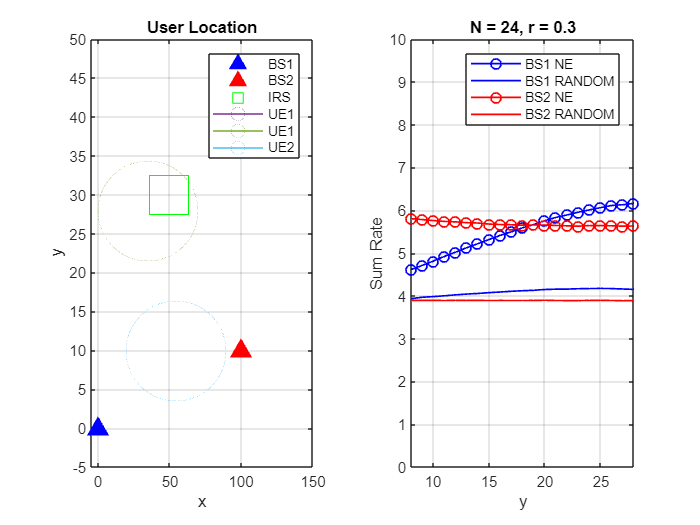

%% plot 1 SumRate
% plot(1  :  SV,s1_star ,'b-s', 'linewidth',1)
% hold on
% plot(1 :  SV, s2_star, 'r-s', 'linewidth',1)
% legend('BS1', 'BS2')
figure
set(gcf,'color','w');   % Set the figure background to white
tiledlayout(1,2)
nexttile
%  draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw BS2
plot(x2,y2,'^','MarkerSize',10,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r','linewidth',1)
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x(1),y(1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
plot(x(1),y(1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% draw BS2 users
plot(x(N1+1),y(N1+1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150]) ; 
ylim([-5 50]) ; 
legend('BS1','BS2','IRS','UE1','UE1','UE2') ; 
grid on
nexttile
% draw results
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
% plot(start : step : (SV-1) * step+start, EPG_final_rate(1,1 : SV),'b-s','linewidth',1)
plot(start : step : (SV-1) * step+start, NE_final_rate(1,1 : SV),'b-o','linewidth',1)
hold on
plot(start : step : (SV-1) * step+start,Random_final_rate(1,1 : i),'b','linewidth',1)
% plot(start : step : (SV-1) * step+start,EPG_final_rate(2,1 : SV),'r-s','linewidth',1)
plot(start : step : (SV-1) * step+start,NE_final_rate(2,1 : SV),'r-o','linewidth',1)
plot(start : step : (SV-1) * step+start,Random_final_rate(2,1 : i),'r','linewidth',1)

legend('BS1 NE','BS1 RANDOM'...
    ,'BS2 NE','BS2 RANDOM') ; 
grid on
title(['N = ' , num2str(N_i) , ', r = ' , num2str(r) ])
xlabel('y')
ylabel('Sum Rate')
xlim([start max((SV-1) * step+start, start+step)]) ; 
ylim([0 10]) ; 

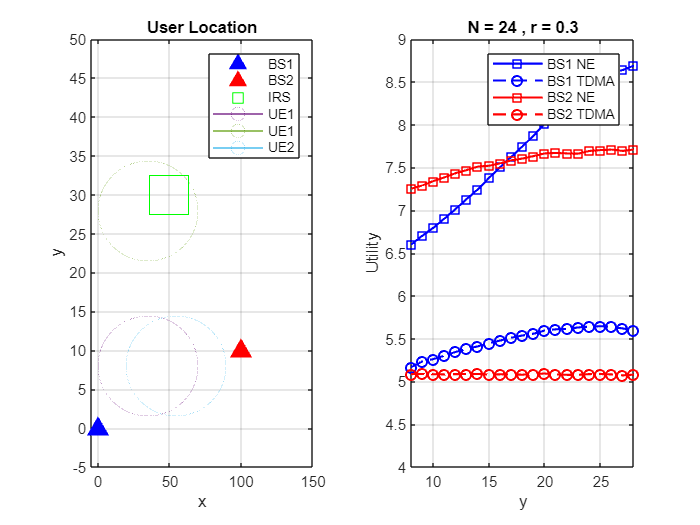

% saveas(gcf,['EPG rate for ', num2str(N_i),' IRS elements-N1= ', num2str(N1),'-N2=',num2str(N2),'.epsc'])
%% plot 2 Utility
figure
tiledlayout(1,2)
nexttile
% draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw BS2
plot(x2,y2,'^','MarkerSize',10,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r','linewidth',1)
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x(1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
plot(x(1),d,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% draw BS2 users
plot(x(N1+1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150]) ; 
ylim([-5 50]) ; 
legend('BS1','BS2','IRS','UE1','UE1','UE2') ; 
grid on
nexttile
% draw results
% plot(start : step : (SV-1) * step+start , EPG_final_utility(1 , 1 : SV) , 'b-s' , 'linewidth' , 1)
plot(start : step : (SV-1) * step+start ,  NE_final_utility(1 , 1 : SV) , 'b-s' , 'linewidth' , 1.25)
hold on
plot(start : step : (SV-1) * step+start , Random_final_utility(1 , 1 : i) , 'b--o' , 'linewidth' , 1.25)
% plot(start : step : (SV-1) * step+start , EPG_final_utility(2 , 1 : SV) , 'r-s' ,  'linewidth' , 1)
plot(start : step : (SV-1) * step+start , NE_final_utility(2 , 1 : SV) , 'r-s' , 'linewidth' , 1.25)
plot(start : step : (SV-1) * step+start , Random_final_utility(2 , 1 : i) , 'r--o' , 'linewidth' , 1.25)

legend('BS1 NE' , 'BS1 TDMA'...
     , 'BS2 NE' , 'BS2 TDMA') ; 
% configs
grid on
set(gcf , 'color' , 'w');   % Set the figure background to white
title(['N = ' , num2str(N_i) , ' , r = ' , num2str(r) ])
xlabel('y')
ylabel('Utility')
xlim([start max((SV-1) * step+start , start+step)]) ; 
ylim([4 9])

% saveas(gcf , ['EPG utility for ' ,  num2str(N_i) , ' IRS elements-N1= ' ,  num2str(N1) , '-N2=' , num2str(N2) , '.epsc'])

## Utility vs No. useres

First we calculate the rates.

%% Calculating Rates
tic
rate = zeros(2 , 2 , 2 , SV) ; 
% var = [] ; 
% save('EPG_utility.mat' , 'var')
% save('rate.mat' , 'var')
% save('loopcounter.mat' , 'var') 
Random_final_rate = zeros(2 , SV) ; 
Random_final_utility = zeros(2 , SV) ; 
step = 1 ;     
start = 4 ;   
m = repmat('.' ,  1 ,  1 + floor((y_i-start)/step)) ; 
tic

for N1 = start + 0  * step : step : start + (SV-1) * step
    N2 = N1 ;
    m(1+floor((N1-start)/step)) = '|' ; 
    disp(m)
%     pause(1)
    % users center location
    x = zeros(N1+N2 , 1) ; 
    y = zeros(N1+N2 , 1) ; 
    z = 1.5 * ones(N1+N2 , 1) ; 
    x(1 : N1 , 1) = 35 ; 
    x(N1+1 : N2+N1) = 55 ; 
    y(1 : N1 , 1) = 15 ; 
    y(N1+1 : N2+N1) = 10 ; 
%     y(1 : N1) = d ; 
    i = 1+floor((N1-start)/step) ; 
   [~ ,  rate( : ,  : ,  : , i)] = TwoStrategyGame(M_t , M_r , N1 , N2 , N_i , P_T , x , y , z , x1 , y1 , z1 ,...
                                        x2 , y2 , z2 , x_i , y_i , z_i , alpha_d , alpha_r , noise_power , N_iter ,...
                                        [R1 ; R2] , r , interference , epsilon) ; 
%     SaveOut('rate.mat' ,rate( : , : , :  ,i)) ;  
%     SaveOut('loopcounter.mat' ,i)
end
toc

Calculate NE

%% NE in EPG and 2 strategy game
% EPG_utility = zeros(2 , 2 , 2 , SV) ; 
utility = zeros(2 , 2 , 2 , SV) ; 
P = zeros(2 , SV , 1) ;
NE_final_rate = zeros(2 , SV) ;
NE_final_utility = zeros(2 , SV) ;
for i = 1 : SV
    N1 = start + (i - 1) * step ;
    N2 = N1 ;
    for s1 = 1 : 2
        for s2 = 1 : 2
            N_i1 = floor((s1-1) * N_i) ;     % No. of elements allocated to BS1
            N_i2 = floor((s2-1) * N_i) ;     % No. of elements allocated to BS2
            if s1 == 2 & s2 == 2
                N_i1 = N_i/2 ;
                N_i2 = N_i/2 ;
            end
            utility(s1 , s2 , 1 ,i) = N1 * rate(s1 , s2 , 1 ,i) - r * N_i1 ;
            utility(s1 , s2 , 2 ,i) = N2 * rate(s1 , s2 , 2 ,i) - r * N_i2 ;
        end
    end
    P( :  ,i) = NE(utility( :  , : ,  :  , i)) ;
    NE_final_rate(  :  , i) = N1 *( P( 1 , i) * P( 2 , i) * rate(1  ,1  , :  , i) +...
                            P( 1 , i) * ( 1 - P(2 , i)) * rate( 1 , end , :  , i) + ...
                            (1 - P( 1 , i) ) * P( 2 , i) * rate( end , 1 ,  :  , i) + ...
                            ( 1 - P( 1 , i) ) * (1 - P( 2 , i) ) * rate( 1 + floor(size(rate , 1)/2) ,1 + floor(size(rate , 2)/2) ,  :  , i)) ;  
    NE_final_utility(  : , i) =  P( 1 , i) * P( 2 , i) * utility(1  ,1  , :  ,i) +...
                           P( 1 , i) * ( 1 - P(2 , i)) * utility( 1 , 2 , :  , i) + ...
                           (1 - P( 1 , i) ) * P( 2 , i) * utility( 2 , 1 ,  :  , i) + ...
                           ( 1 - P( 1 , i) ) * (1 - P( 2 , i) ) * utility( 2 , 2 ,  :  , i) ; 
                       
%    Random Resource allocation for IRS 
    Random_final_rate(1 , i) = 0.25 * sum(sum(rate(: ,: ,1 , i))) ; 
    Random_final_rate(2 , i) = 0.25 * sum(sum(rate(: ,: ,2 , i))) ; 
    Random_final_utility(1 , i) = 0.25 * sum(sum(utility(: ,: ,1 , i))) ; 
    Random_final_utility(2 , i) = 0.25 * sum(sum(utility(: ,: ,2 , i))) ; 
end
disp(P)
toc

Plot

%% plot 1 SumRate
% plot(1  :  SV,s1_star ,'b-s', 'linewidth',1)
% hold on
% plot(1 :  SV, s2_star, 'r-s', 'linewidth',1)
% legend('BS1', 'BS2')
figure
set(gcf,'color','w');   % Set the figure background to white
tiledlayout(1,2)
nexttile
%  draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw BS2
plot(x2,y2,'^','MarkerSize',10,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r','linewidth',1)
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x(1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% plot(x(1),d,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% draw BS2 users
plot(x(N1+1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150]) ; 
ylim([-5 50]) ; 
legend('BS1','BS2','IRS','UE1','UE2') ; 
grid on
nexttile
% draw results
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
% plot(start : step : (SV-1) * step+start, EPG_final_rate(1,1 : SV),'b-s','linewidth',1)
plot(start : step : (SV-1) * step+start, NE_final_rate(1,1 : SV),'b-o','linewidth',1)
hold on
plot(start : step : (SV-1) * step+start,Random_final_rate(1,1 : SV),'b','linewidth',1)
% plot(start : step : (SV-1) * step+start,EPG_final_rate(2,1 : SV),'r-s','linewidth',1)
plot(start : step : (SV-1) * step+start,NE_final_rate(2,1 : SV),'r-o','linewidth',1)
plot(start : step : (SV-1) * step+start,Random_final_rate(2,1 : SV),'r','linewidth',1)

legend('BS1 NE','BS1 RANDOM'...
    ,'BS2 NE','BS2 RANDOM') ; 
grid on
title(['N = ' , num2str(N_i) , ', r = ' , num2str(r) ])
xlabel('y')
ylabel('Sum Rate')
xlim([start max((SV-1) * step+start, start+step)]) ; 
ylim([0 10]) ; 

% saveas(gcf,['EPG rate for ', num2str(N_i),' IRS elements-N1= ', num2str(N1),'-N2=',num2str(N2),'.epsc'])

%% plot 2 Utility
figure
tiledlayout(1,2)
nexttile
% draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw BS2
plot(x2,y2,'^','MarkerSize',10,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r','linewidth',1)
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x(1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
plot(x(1),d,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% draw BS2 users
plot(x(N1+1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150]) ; 
ylim([-5 50]) ; 
legend('BS1','BS2','IRS','UE1','UE1','UE2') ; 
grid on
nexttile
% draw results
% plot(start : step : (SV-1) * step+start , EPG_final_utility(1 , 1 : SV) , 'b-s' , 'linewidth' , 1)
plot(start : step : (SV-1) * step+start ,  NE_final_utility(1 , 1 : SV) , 'b-o' , 'linewidth' , 1)
hold on
plot(start : step : (SV-1) * step+start , Random_final_utility(1 , 1 : SV) , 'b' , 'linewidth' , 1)
% plot(start : step : (SV-1) * step+start , EPG_final_utility(2 , 1 : SV) , 'r-s' ,  'linewidth' , 1)
plot(start : step : (SV-1) * step+start , NE_final_utility(2 , 1 : SV) , 'r-o' , 'linewidth' , 1)
plot(start : step : (SV-1) * step+start , Random_final_utility(2 , 1 : SV) , 'r' , 'linewidth' , 1)


% legend('BS1 EPG' , 'BS2 EPG' ,  'BS1 NE' ,  'BS2 NE') ; 
legend('BS1 NE' , 'BS1 RANDOM'...
     , 'BS2 NE' , 'BS2 RANDOM') ; 
% configs
grid on
set(gcf , 'color' , 'w');   % Set the figure background to white
title(['N = ' , num2str(N_i) , ' , r = ' , num2str(r) ])
xlabel('y')
ylabel('Utility')
xlim([start max((SV-1) * step+start , start+step)]) ; 
ylim([0 10]) ; 
% saveas(gcf , ['EPG utility for ' ,  num2str(N_i) , ' IRS elements-N1= ' ,  num2str(N1) , '-N2=' , num2str(N2) , '.epsc'])
